## **CU Anschutz-Medtronic Percieve Collaboration**

The purpose of this report is to illustarte key findings from the data acquisition and early analysis portion of this study. 

This section loads in variables that are useful to the other fuctions. Further, this section helps to process files coming from a patient with either single or double batteries, enhancing the modularity of the code. 

%%
clear
cd('C:\Users\sydne\Documents\github\perceive')
jsonFiles = 'Report_Json_Session_Report_20210604T094200.json';
cd('C:\Users\sydne\Documents\github\perceive')
js = jsondecode(fileread(jsonFiles));

channels = unique({js.LfpMontageTimeDomain.Channel}, 'stable');
leng = numel({js.LfpMontageTimeDomain.Channel});
sides = {'LEFT', 'RIGHT'};
startindex = 1; 
if any((contains(channels, sides{1}))) && any((contains(channels, sides{2}))) 
        doubleBattery = false; 
        %json has both left and right data 
        channelsLeft = channels(contains(channels, sides{1}));
        channelsRight = channels(contains(channels, sides{2}));
        highestBetas = cell(2);
    else 
        doubleBattery = true; 
end 

#### Frequency vs power plot for all contact pairs

After data is collected from Brainsense, the three trials are averaged and presented as a single line. All six pairs are represented. Smoothing has maintained the shape of the curve but altered the power, thus not always matching the maximum power reported. 

The highest beta comes from contact pair 02


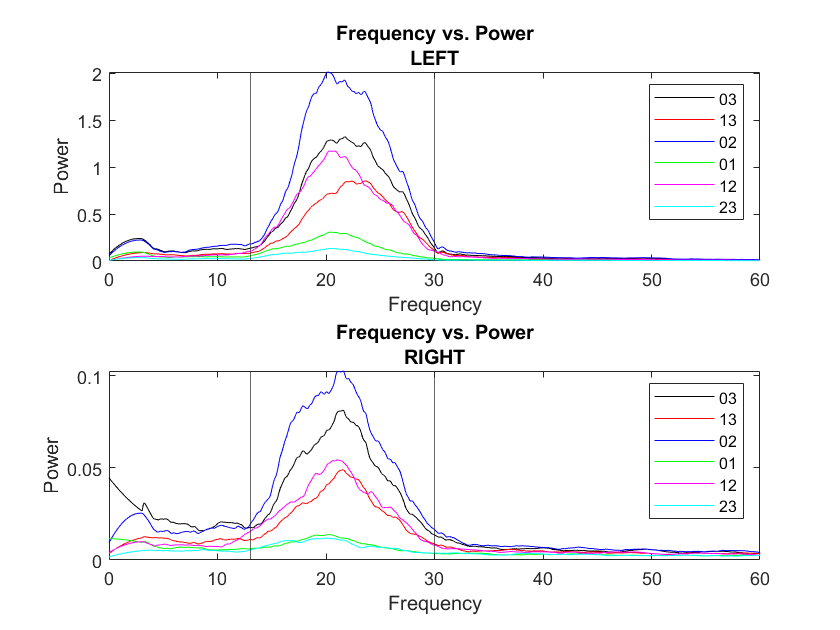

The highest beta comes from contact pair 02


    for  i = 1:2
        subplot(2, 1, i)
        channels2 = channels(contains(channels,sides{i}));
        colors = 'krbgmc';
        maxValues = zeros(length(channels2), 1);
        for c=1:length(channels2)
            maxValues(c) = tempAvgPlot(startindex, leng, js, channels2{c}, colors(c));
            hold on;
        end
        
        [M, I] = max(maxValues);
        highestBeta = channels2{I};
        highestBetas{i} = highestBeta;
        
        %add all the plot info
        xline(13);
        xline(30);
        
        %formats the channels to be suitable for the legend 
        legendChan = cell(6);
        oldchar = {'LEFT', 'RIGHT', '0', '1', '2', '3', '4', '5', '_', 'AND'}; 
        newchar = {''}; 
        oldnum = {'ZERO', 'ONE', 'TWO', 'THREE'}; 
        newnum = {'0', '1', '2', '3'};
        for b = 1:length(channels2)
            legendChan{b} = replace(channels2{b}, oldchar, newchar);
            legendChan{b} = replace(legendChan{b}, oldnum, newnum);
        end
        legend(legendChan{1}, legendChan{2}, legendChan{3}, legendChan{4}, legendChan{5}, legendChan{6})
        
        
        title(["Frequency vs. Power", sides{i}])
        xlim([0 60])
        xlabel("Frequency")
        ylabel("Power")
        
        disp(['The highest beta comes from contact pair ', legendChan{I}])
    end

#### Compare beta between contacts with standard deviation 

For both the left and right sides, the average between all three trials is taken. Then, the max is found within the beta region and plotted. Standard devation is of the average of the three trails and within the beta region. 

    disp("Beta bar chart summary for the LEFT")

Beta bar chart summary for the LEFT


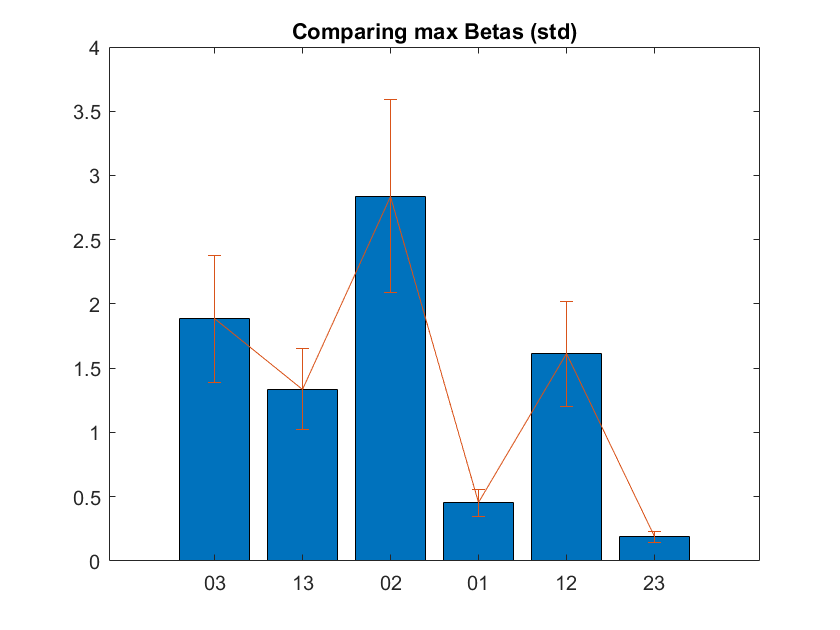

    compareBetaBarChart(startindex, leng, js, channelsLeft); 

    disp("Beta bar chart summary for the RIGHT")

Beta bar chart summary for the RIGHT


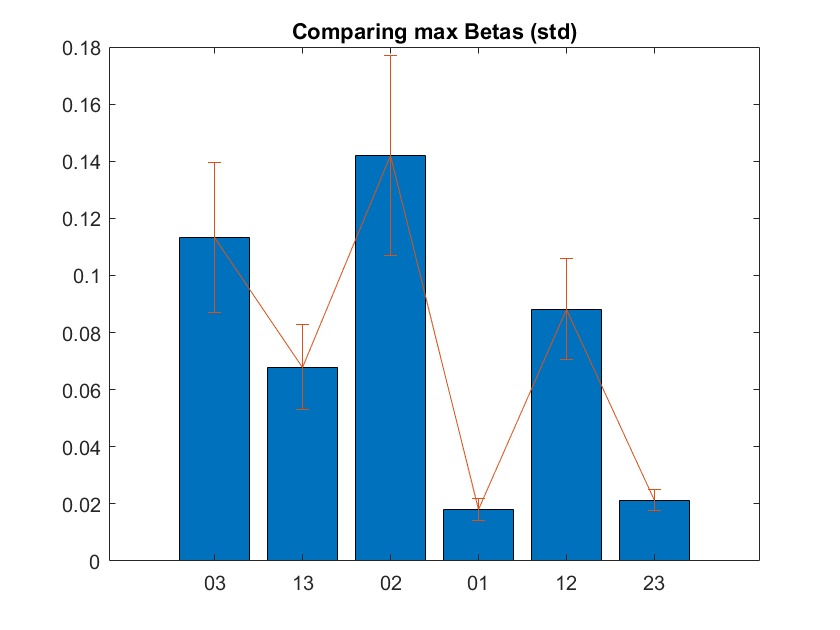

    compareBetaBarChart(startindex, leng, js, channelsRight);

    figure;

#### All frequency spectrum for max beta contacts

For the contact pair that is determined to produce the most beta, full spectrum analysis was performed. Delta is defined as between 0-4.99Hz, theta is between 5-8.99Hz, alpha is 9-11.99Hz, beta is 12-33.99Hz, and gamma is from 34-100Hz. Data is shown for the left and right. 

    disp("All frequency bar chart summary for the LEFT")

All frequency bar chart summary for the LEFT


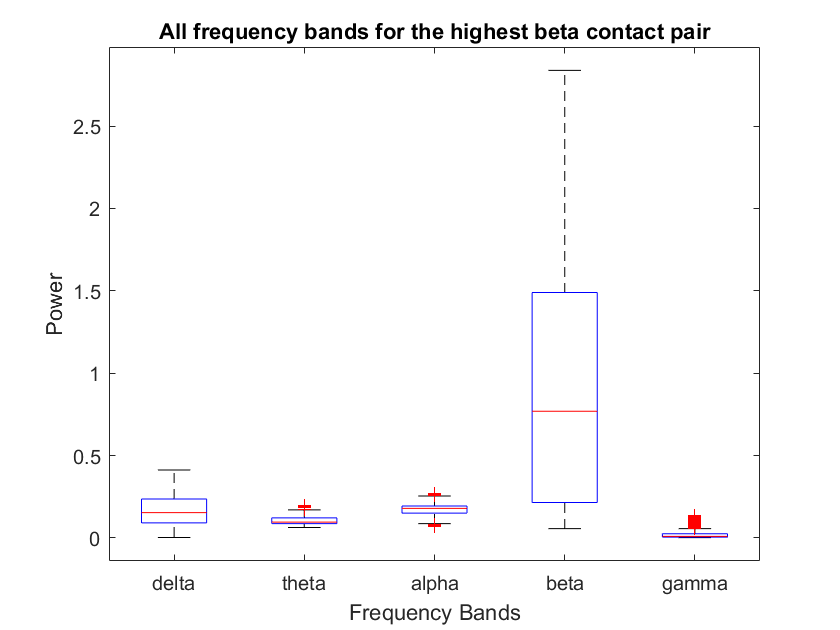

    allFreqBarChart(startindex, leng, js, highestBetas{1})

    figure;
    disp("All frequency bar chart summary for the Right")

All frequency bar chart summary for the Right


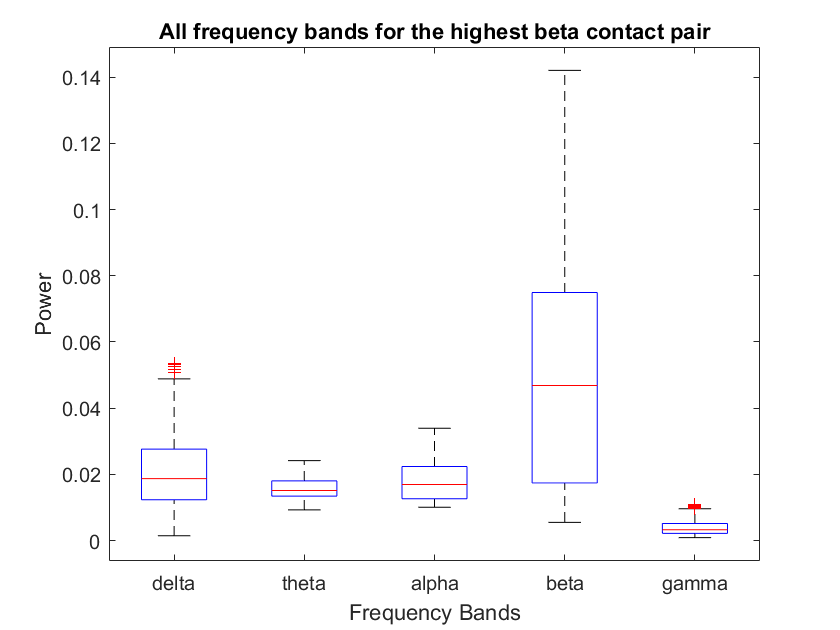

    allFreqBarChart(startindex, leng, js, highestBetas{2}) 

    figure;

#### Mean and Standard Deviation for each Trial

In descending order of beta activity, the means and stds of each contact pair is displayed. Each contact pair has the mean and std for each trial listed. These values come only from the beta region. A more concise visualization is below. Data is for the left and right. 

   %% 
   disp("Table trial summary for the LEFT")

Table trial summary for the LEFT


   maxMeanBetaAllRuns(startindex, js, leng, channelsLeft); 

ans = 6×7 table
              Var1              Mean R1     Mean R2     Mean R3     STD R1      STD R2      STD R3 
    ________________________    ________    ________    _______    ________    ________    ________

    {'ZERO_TWO_LEFT_2'     }      1.1235      1.3256     1.0068     0.87504     0.93069     0.74441
    {'ZERO_THREE_LEFT_0'   }     0.68224      0.9442    0.70638     0.53611     0.65692     0.50726
    {'ONE_AND_TWO_LEFT_1'  }     0.65589     0.69293     0.5461     0.49253     0.43155     0.45486
    {'ONE_THREE_LEFT_1'    }     0.42279     0.58601    0.46806     0.33974     0.40995     0.35274
    {'ZERO_AND_ONE_LEFT_0' }      0.1503     0.18418    0.15133     0.11469     0.11598      0.1287
    {'TWO_AND_THREE_LEFT_2'}    0.074978    0

   disp("Table trial summary for the RIGHT")

Table trial summary for the RIGHT


   maxMeanBetaAllRuns(startindex, js, leng, channelsRight);

ans = 6×7 table
              Var1                Mean R1      Mean R2      Mean R3      STD R1       STD R2       STD R3  
    _________________________    _________    _________    _________    _________    _________    _________

    {'ZERO_TWO_RIGHT_5'     }     0.050325     0.077603     0.057598     0.037565     0.057483     0.032637
    {'ZERO_THREE_RIGHT_3'   }     0.040915     0.057103     0.042317     0.028979       0.0414     0.025036
    {'ONE_AND_TWO_RIGHT_4'  }     0.035766     0.032432     0.026359     0.030524     0.019073     0.012064
    {'ONE_THREE_RIGHT_4'    }     0.024048     0.031501     0.025468     0.016749     0.021688     0.014984
    {'ZERO_AND_ONE_RIGHT_3' }    0.0087138    0.0086466    0.0079615     0.005922      0.00486   

#### Visualization of Trial Variability

For each contact, all three trials are plotted together to illustrate the variability from run-to-run for each Brainsense survey. Data has undergone smoothing that maintains the shape but not nessicarily the values. More granular information is in the table above. 

   disp("Graph trial summary for the LEFT")

Graph trial summary for the LEFT


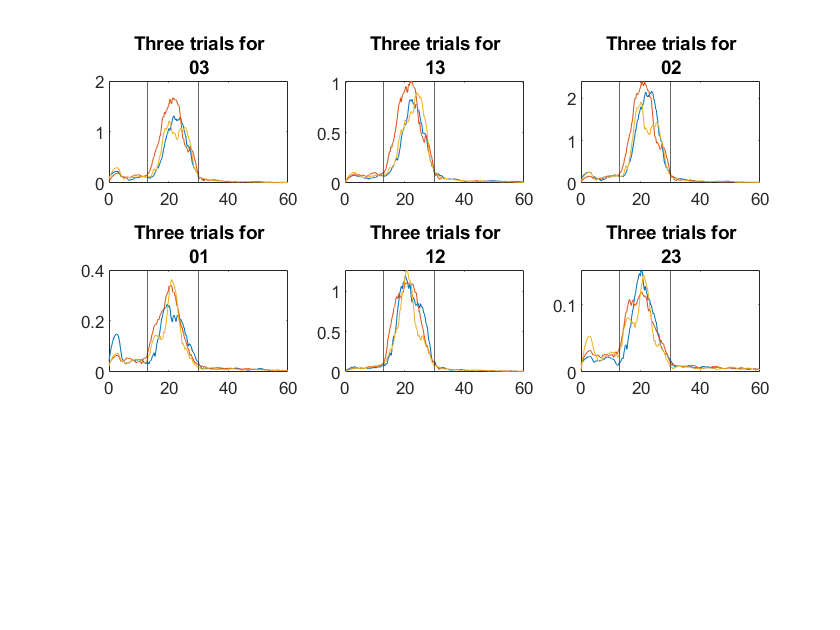

   graphEachTrials(startindex, js, leng, channelsLeft);

   figure;
   disp("Graph trial summary for the RIGHT")

Graph trial summary for the RIGHT


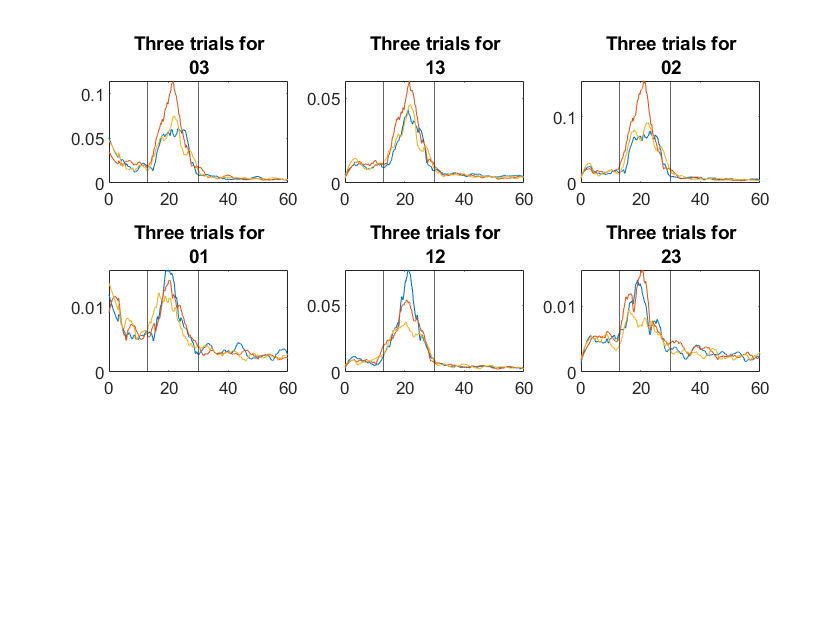

   graphEachTrials(startindex, js, leng, channelsRight);